# Constructing the forward model

## **Introduction**

This section will cover how to contruct the head model (the forward model implemented as a lead field matrix) to be used in source modeling. This will done based on the structural T1 MRI.

## **Preparation**

Make sure FieldTrip is installed and path is set. Then run ft_defaults (only needs running once during each Matlab session). 

ft_defaults

Set the path and the file names of the fif files. We will be using the MaxFiltered data.

data_path = 'C:\YOUR_DATA_FOLDER\';
mri_data_path = 'C:\Users\Tamas\Documents\';

Load the cleaned gradiometer data.

load([data_path,'planar_clean.mat'])

## **Co-registration with anatomical landmarks**

For co-registering the MEG data and the anatomical MRI scan, you will need to specify the MEG dataset (one datafile is enough) and the MRI nifti file (if the MRI scan is in dicom format any dcm file of the T1 scan will do). 

megfile=[data_path,'training_rawsss-1.fif'];
mrifile=[mri_data_path,'T1_mri.nii'];

Next, we will read the anatomical mri scan in. 

mri = ft_read_mri(mrifile)

 In ft_estimate_units at line 58
 In ft_determine_units at line 113
 In ft_read_mri at line 554



mri = struct with fields:
          dim: [256 256 208]
      anatomy: [256×256×208 double]
          hdr: [1×1 struct]
    transform: [4×4 double]
         unit: 'mm'


The 208 dicom files are each a 256x256 size sagittal MRI slice. The  anatomy field which is made up of all the slices has a diminution of 256x256x208. The header field ('hdr') contains information about the MRI scan.    

If you plot the new 'mri' structure, the picture appears to be flipped. Please note that the mri is "defaced" for anonymization purposes, hence large part of the face area is missing.

the input is volume data with dimensions [256 256 208]
scaling anatomy to [0 1]
not plotting functional data
not applying a mask on the functional data
not using an atlas
not using a region-of-interest


 In ft_sourceplot>cb_redraw at line 1793
 In ft_sourceplot at line 1097



click left mouse button to reposition the cursor
click and hold right mouse button to update the position while moving the mouse
use the arrowkeys to navigate in the current axis


the call to "ft_sourceplot" took 1 seconds


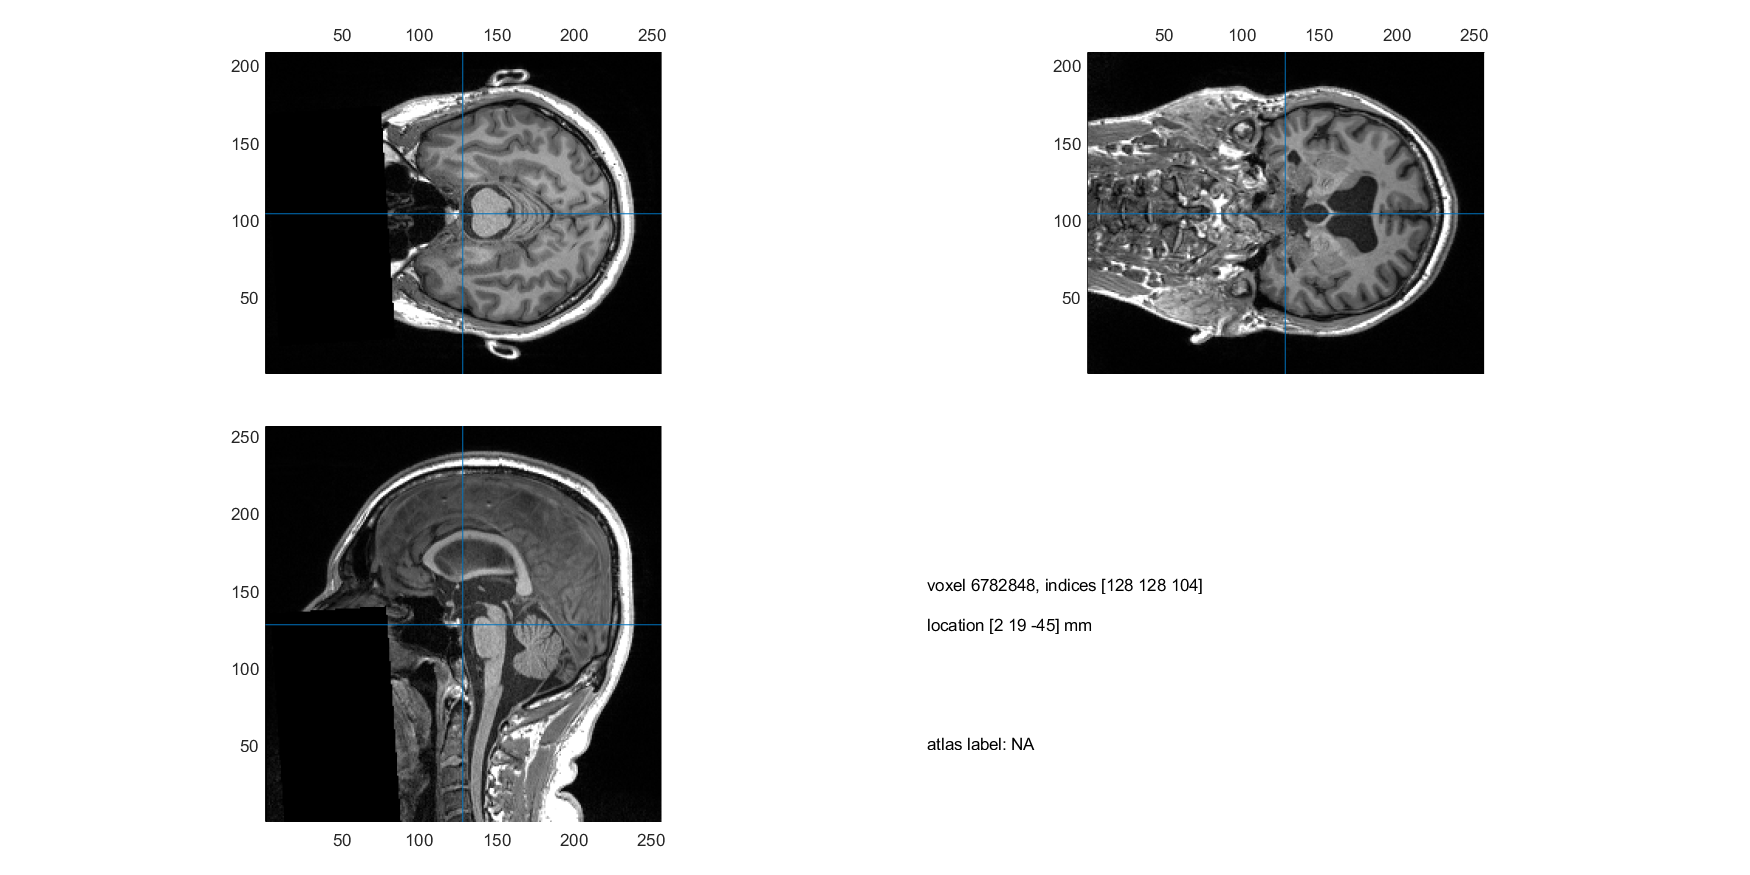

ft_sourceplot([], mri);

To fix the orientation we can use the ft_volumereslice function. 

mri_reslice=ft_volumereslice([],mri)

the input is volume data with dimensions [256 256 208]
reslicing from [256 256 208] to [256 256 256]
the input is volume data with dimensions [256 256 256]
the input is volume data with dimensions [256 256 208]
selecting subvolume of 62.1%
reslicing and interpolating aninterpolating 100.0
the call to "ft_sourceinterpolate" took 8 seconds
the call to "ft_volumereslice" took 8 seconds


mri_reslice = struct with fields:
      anatomy: [256×256×256 double]
          dim: [256 256 256]
    transform: [4×4 double]
         unit: 'mm'
          cfg: [1×1 struct]


Plot the resliced mri structure:

the input is volume data with dimensions [256 256 256]
scaling anatomy to [0 1]
not plotting functional data
not applying a mask on the functional data
not using an atlas
not using a region-of-interest


 In ft_sourceplot>cb_redraw at line 1793
 In ft_sourceplot at line 1097



click left mouse button to reposition the cursor
click and hold right mouse button to update the position while moving the mouse
use the arrowkeys to navigate in the current axis


the call to "ft_sourceplot" took 1 seconds


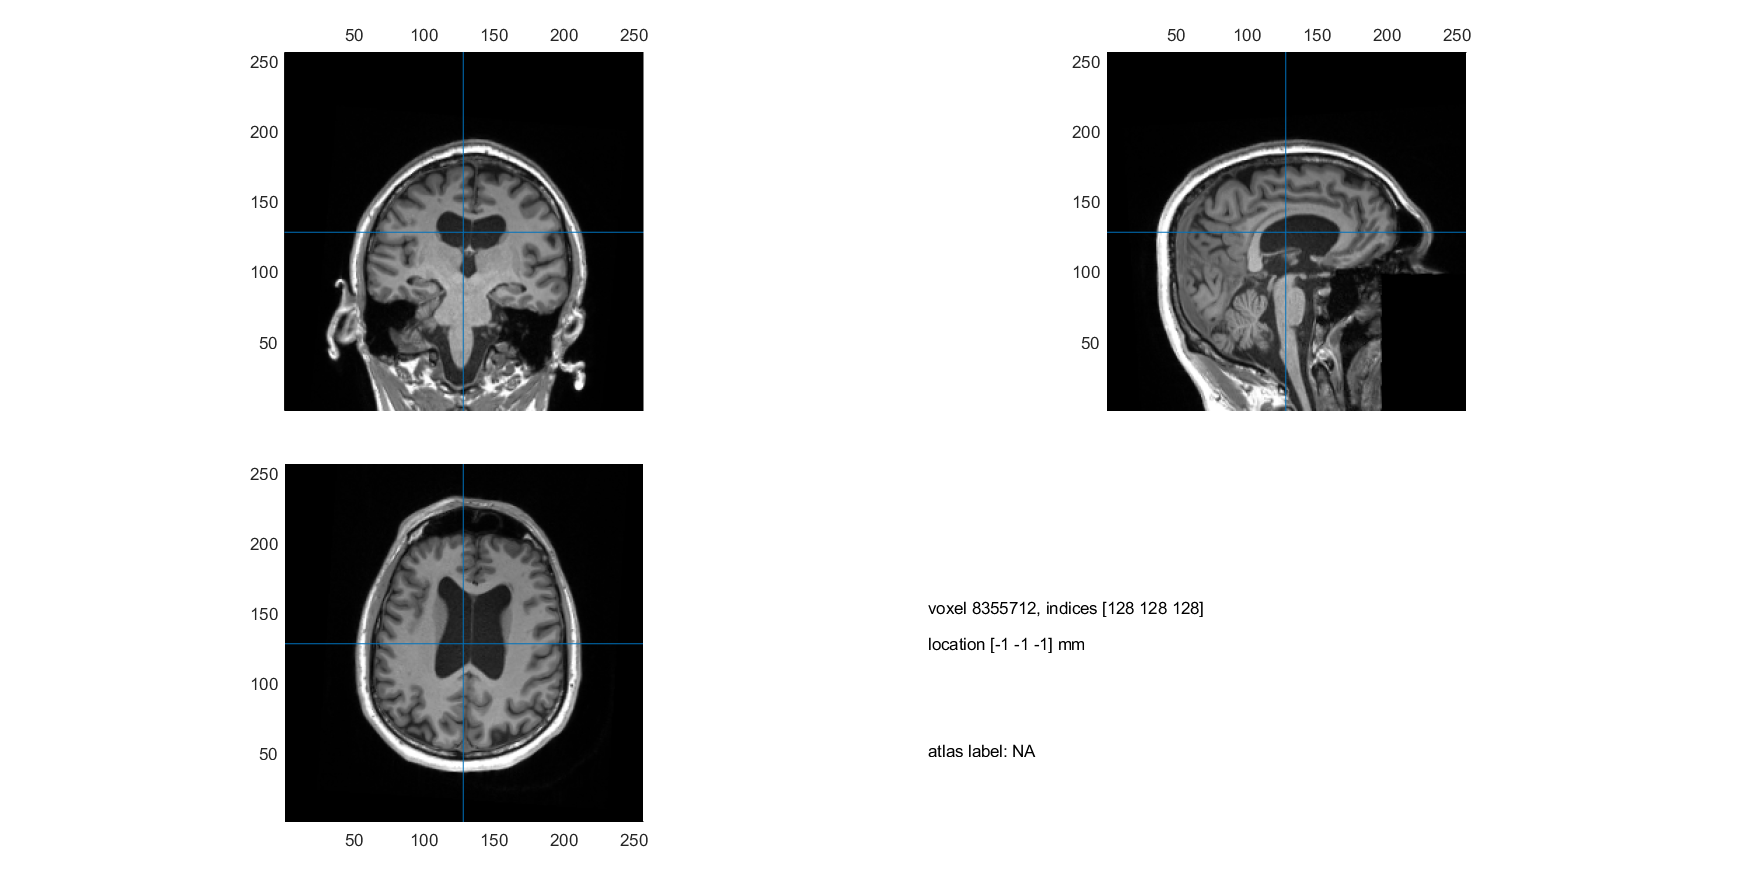

ft_sourceplot([], mri_reslice);

ft_volumreslice realigned the volume so it does not appear to be flipped anymore, and also made the volume symmetrical across the 3 dimensions. Thus the anatomy field now is a 256x256x256 matrix.  

Next we will read the digitized headshape and landmark points of the Polhemus digitization which was part of the MEG recording.  

headshape=ft_read_headshape(megfile)

	306 MEG channel locations transformed
Reading C:\Users\Tamas\Documents\training_rawsss-1.fif ...
Opening raw data file C:\Users\Tamas\Documents\training_rawsss-1.fif...
	Range : 208000 ... 1664999  =    208.000 ...  1664.999 secs
Ready.


 In ft_datatype_sens at line 325
 In ft_datatype_sens at line 207
 In ft_datatype_sens at line 180
 In ft_read_header at line 2841
 In read_neuromag_hc at line 47
 In ft_read_headshape at line 494



headshape = struct with fields:
         pos: [400×3 double]
         fid: [1×1 struct]
       label: {400×1 cell}
    coordsys: 'neuromag'
        unit: 'cm'


Read the channel information in and plot the landmark points, additional digitized headpoints and the channels. 

grad=ft_read_sens(megfile,'senstype','meg');

	306 MEG channel locations transformed
Reading C:\Users\Tamas\Documents\training_rawsss-1.fif ...
Opening raw data file C:\Users\Tamas\Documents\training_rawsss-1.fif...
	Range : 208000 ... 1664999  =    208.000 ...  1664.999 secs
Ready.


Plot the headshape points and the sensors:

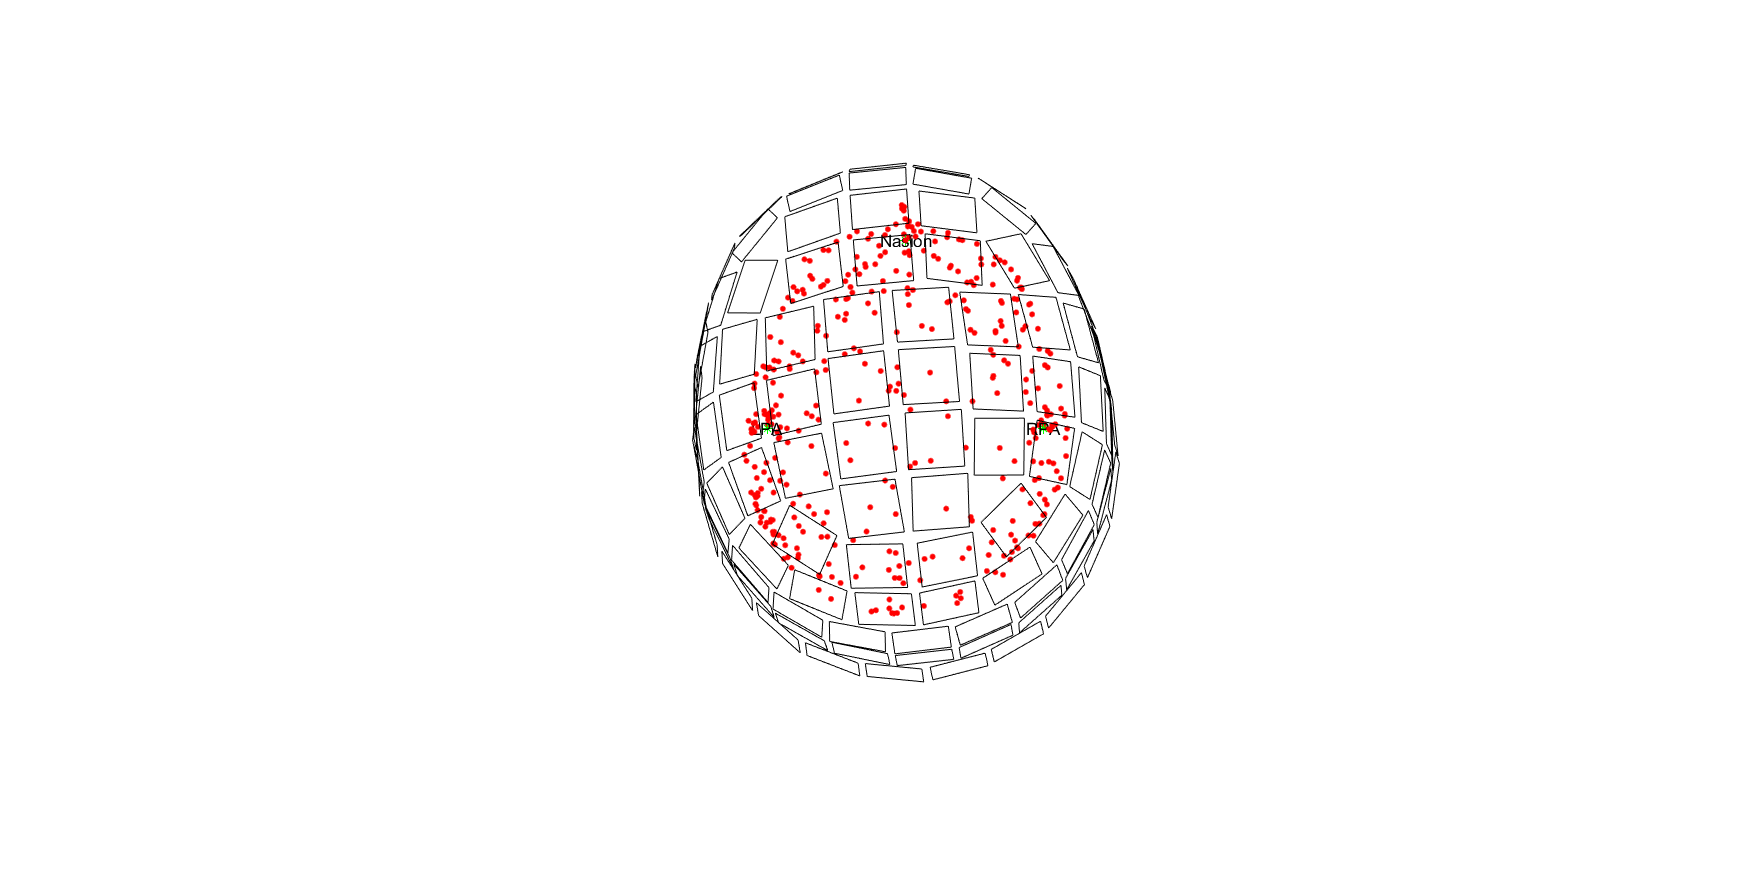

figure;
ft_plot_headshape(headshape);
ft_plot_sens(grad);

Now coregister the MRI scan with the MEG recording by bringing the MRI scan to Neuromag coordinate system, same as the MEG recording. To do so you will need to mark the cardinal landmark points (LPA, RPA and nasion) on the MRI scan by running the ft_volumerealign function. Fieldtrip will then bring the scan to Neuromag coordinates ('cfg.coordsys='neuromag*).*

the input is volume data with dimensions [256 256 256]


1. To change the slice viewed in one plane, either:
   a. click (left mouse) in the image on a different plane. Eg, to view a more
      superior slice in the horizontal plane, click on a superior position in the
      coronal plane, or
   b. use the arrow keys to increase or decrease the slice number by one
2. To mark a fiducial position or anatomical landmark, do BOTH:
   a. select the position by clicking on it in any slice with the left mouse button
   b. identify it by pressing the letter corresponding to the fiducial/landmark:
      press n for nas, l for lpa, r for rpa
      press z for an extra control point that should have a positive z-value
   You can mark the fiducials multiple times, until you are satisfied with the positions.
3. To change the display:
   a. press c on keyboard to toggle crosshair visibility
   b. press f on keyboard to toggle fiducial visibility
   c. press + or - on (numeric) keyboard to change the color range's upper limit
4. To finalize markers and qui

 In ft_estimate_units at line 51
 In ft_plot_slice at line 219
 In ft_plot_ortho at line 126
 In ft_volumerealign>cb_redraw at line 1463
 In ft_volumerealign at line 1310



 In ft_estimate_units at line 51
 In ft_plot_slice at line 219
 In ft_plot_ortho at line 143
 In ft_volumerealign>cb_redraw at line 1463
 In ft_volumerealign at line 1310



 In ft_estimate_units at line 51
 In ft_plot_slice at line 219
 In ft_plot_ortho at line 160
 In ft_volumerealign>cb_redraw at line 1463
 In ft_volumerealign at line 1310



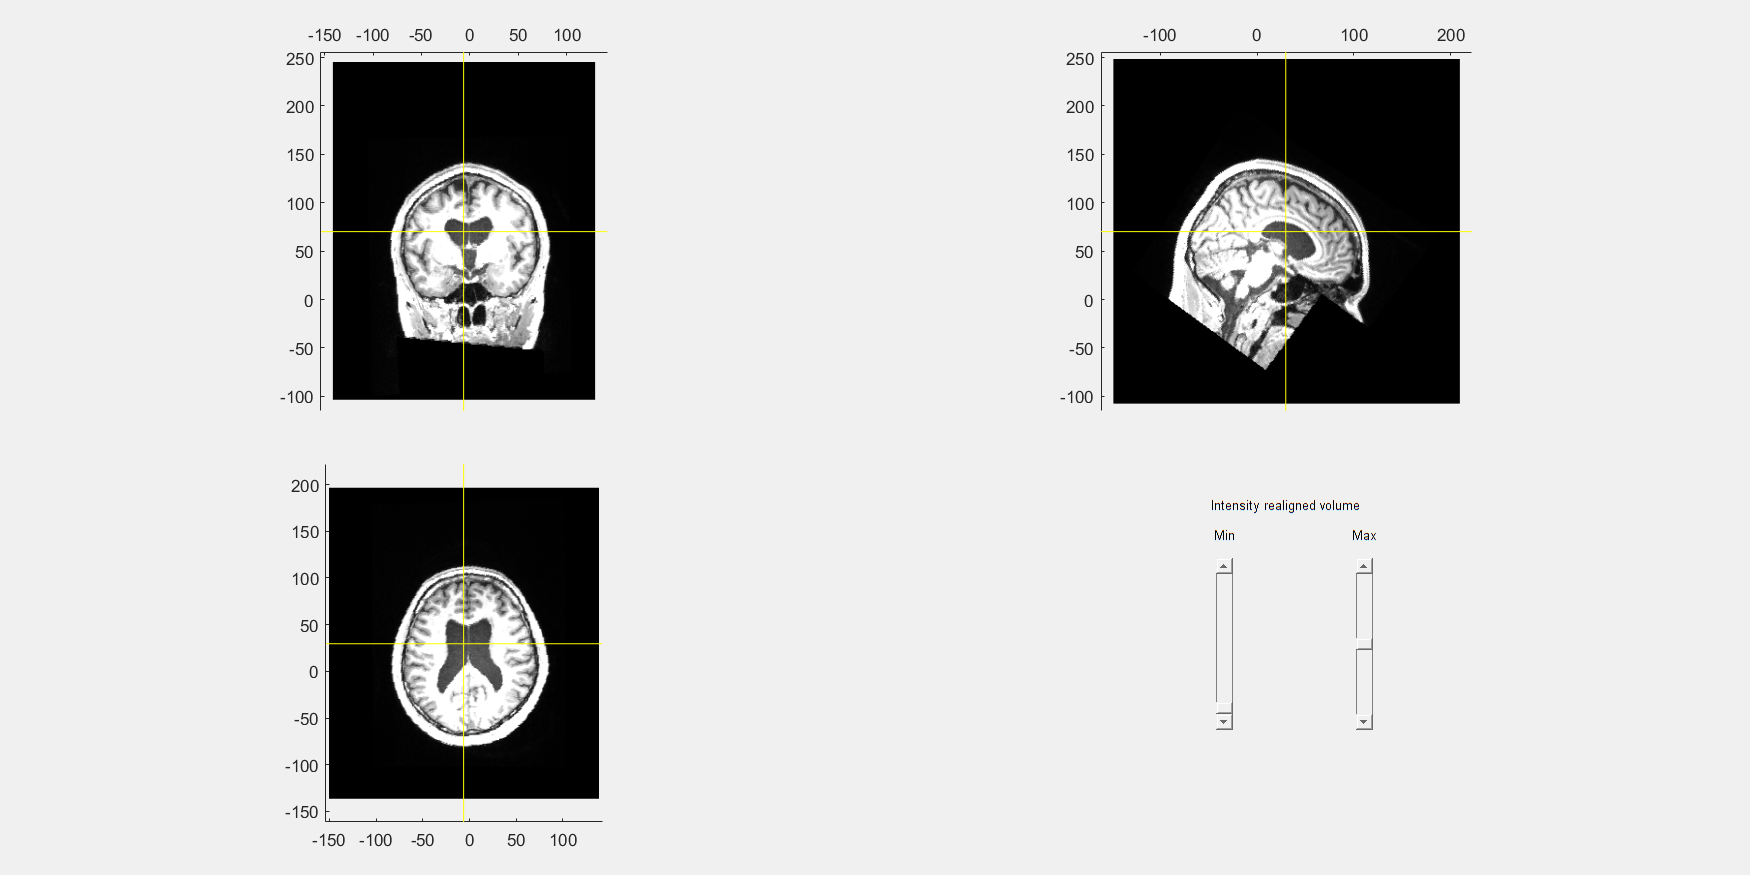

the call to "ft_volumerealign" took 74 seconds


mri_realigned1 = struct with fields:
          anatomy: [256×256×256 double]
              dim: [256 256 256]
        transform: [4×4 double]
             unit: 'mm'
              cfg: [1×1 struct]
    transformorig: [4×4 double]
         coordsys: 'neuromag'


cfg=[];
cfg.viewresult='yes';
cfg.method='interactive';
cfg.coordsys='neuromag';
mri_realigned2=ft_volumerealign(cfg,mri_reslice)

After running the function an interactive figure will pop up. You  will need to find the left preauricular (LPA), the right preauricular point (RPA) and the nasion on the scan and press l,p and n, respectively. This will tell where these landmarks are on the scan and so Fieldtrip will translate the scan into the Neuromag coordinate system according to the marked points. 

The new structure has a new field ('coordys'), which suggests that the scan is now in Neuromag coordinates. 

Have a look at the realigned MRI plot.

the input is volume data with dimensions [256 256 256]
scaling anatomy to [0 1]
not plotting functional data
not applying a mask on the functional data
not using an atlas
not using a region-of-interest


 In ft_sourceplot>cb_redraw at line 1793
 In ft_sourceplot at line 1097



click left mouse button to reposition the cursor
click and hold right mouse button to update the position while moving the mouse
use the arrowkeys to navigate in the current axis


the call to "ft_sourceplot" took 1 seconds


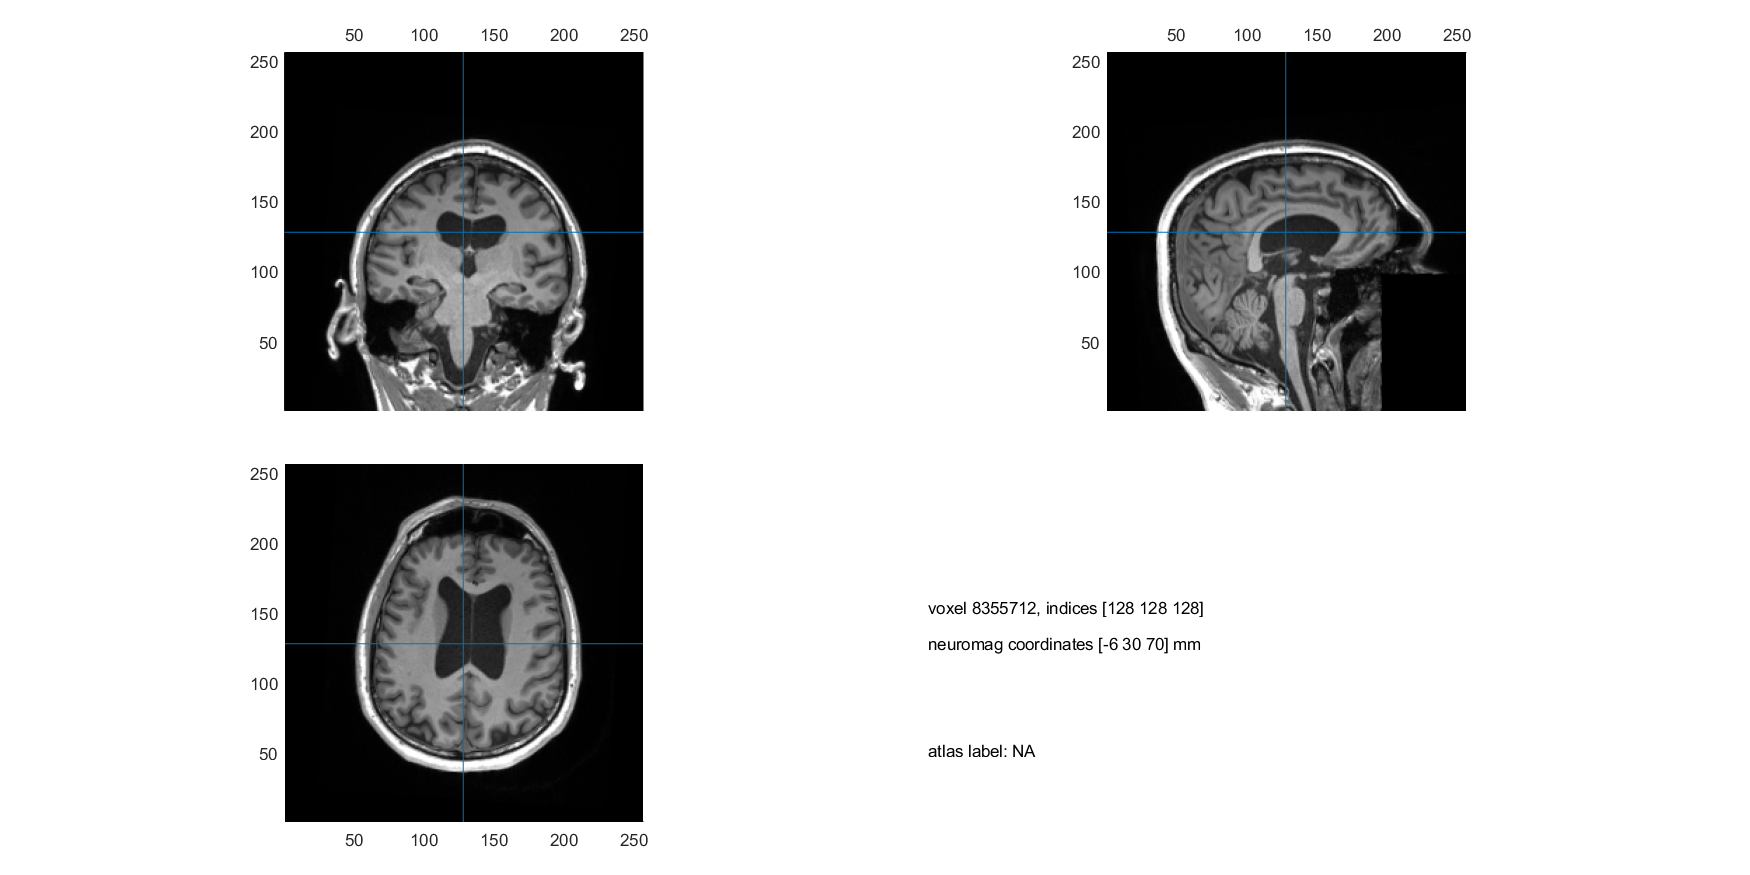

ft_sourceplot([], mri_realigned1);

 For more information on the Neuromag coordinate system and other coordinate systems see [http://www.fieldtriptoolbox.org/faq/how_are_the_different_head_and_mri_coordinate_systems_defined/](http://www.fieldtriptoolbox.org/faq/how_are_the_different_head_and_mri_coordinate_systems_defined/). 

Next we will plot the landmark points, the additional headpoints in conjunction with the anatomical scan. To do so first we will need to  bring the MRI scan and the headpoints to the same measurement unit  ('cm') as the headpoints.  

headshape=ft_convert_units(headshape,'cm');
mri_realigned1=ft_convert_units(mri_realigned1,'cm');

Next we need to extract the coordinates of the landmark points:

nas = ft_warp_apply(mri_realigned1.transform, [mri_realigned1.cfg.fiducial.nas]);
lpa = ft_warp_apply(mri_realigned1.transform, [mri_realigned1.cfg.fiducial.lpa]);
rpa = ft_warp_apply(mri_realigned1.transform, [mri_realigned1.cfg.fiducial.rpa]);

Now we can plot: 

ft_determine_coordsys(mri_realigned1,'interactive','no')

The positive x-axis is pointing towards the right
The positive y-axis is pointing towards anterior
The positive z-axis is pointing towards superior


The axes are 15 cm long in each direction
The diameter of the sphere at the origin is 1 cm


ans = struct with fields:
          anatomy: [256×256×256 double]
              dim: [256 256 256]
        transform: [4×4 double]
             unit: 'cm'
              cfg: [1×1 struct]
    transformorig: [4×4 double]
         coordsys: 'neuromag'


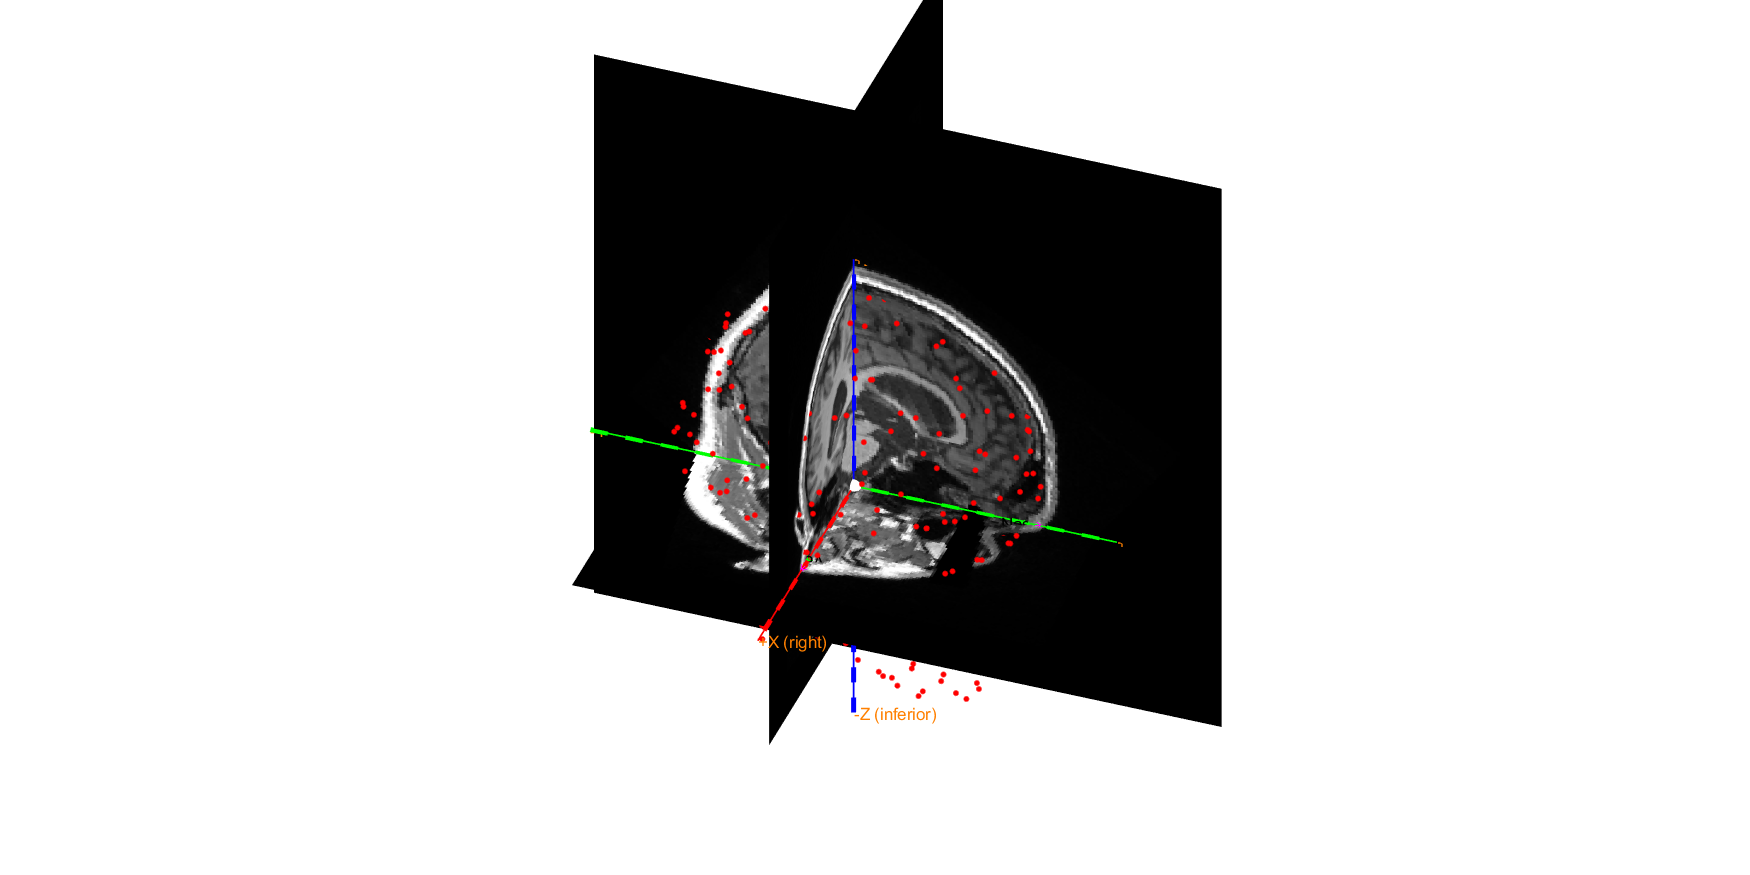

hold on;
ft_plot_headshape(headshape);
plot3(nas(1,1), nas(1,2), nas(1,3), 'm*');
plot3(lpa(1,1), lpa(1,2), lpa(1,3), 'm*');
plot3(rpa(1,1), rpa(1,2), rpa(1,3), 'm*');

To fine-tune the alignment between the MRI scan and the MEG recording, we call ft_volumrealignment function in once more, but with the 'headshape' method. By doing so we can align the MRI headsurface to the digitized  additional headpoints and cardinal landmark points. You will need to  modify the rotate, scale and translate values to make adjustments. 

cfg=[];
cfg.method='headshape';
cfg.headshape.headshape=headshape;
cfg.headshape.icp='yes';
cfg.coordsys='neuromag';
mri_realigned3 =ft_volumerealign(cfg,mri_realigned1);

the input is volume data with dimensions [256 256 256]
the input is volume data with dimensions [256 256 256]
creating scalpmask ... using the anatomy field for segmentation
smoothing anatomy with a 2-voxel FWHM kernel
thresholding anatomy at a relative threshold of 0.100
the call to "ft_volumesegment" took 9 seconds
triangulating the outer boundary of compartment 1 (scalp) with 20000 vertices
the call to "ft_prepare_mesh" took 6 seconds
doing interactive realignment with headshape
Use the mouse to rotate the geometry, and click "redisplay" to update the light.
Close the figure when you are done.


this returns a light skin, you can also explicitly specify 'skin_light',' skin_medium_light', 'skin_medium', 'skin_medium_dark', or 'skin_dark'


the template coordinate system is "neuromag"
the positive X-axis is pointing to the right
the positive Y-axis is pointing to anterior
the positive Z-axis is pointing to superior


the call to "ft_interactiverealign" took 108 seconds
doing iterative closest points realignment with headshape
the input is mesh data with 20000 vertices and 39996 triangles
the input is source data with 20000 brainordinates
the input is source data with 379 brainordinates
interpolating distance
the call to "ft_sourceinterpolate" took 8 seconds
the input is mesh data with 20000 vertices and 39996 triangles
the input is source data with 20000 brainordinates
the input is source data with 379 brainordinates
interpolating distance
the call to "ft_sourceinterpolate" took 7 seconds
the call to "ft_volumerealign" took 143 seconds


## **Forward model**

To create the forward model, first we need to distinguish parts of the MRI scan which represent the brain and others outside of it. For this purpose we can use the ft_volumesegment function, which will be using the external SPM toolbox to perform the segmentation.  

NOTE: you may also want to also specify the skull and scalp, especially if you are using EEG.  


cfg=[];
cfg.output = {'brain'};
mri_segm=ft_volumesegment(cfg,mri_realigned2)

the input is volume data with dimensions [256 256 256]
using 'OldNorm' normalisation
Smoothing by 0 & 8mm..
Coarse Affine Registration..


Fine Affine Registration..
performing the segmentation on the specified volume, using the old-style segmentation

SPM12: spm_preproc (v4916)                         10:35:05 - 06/01/2022
Completed                               :          10:38:44 - 06/01/2022
creating brainmask ... using the summation of gray, white and csf tpms
smoothing brainmask with a 5-voxel FWHM kernel
thresholding brainmask at a relative threshold of 0.500
the call to "ft_volumesegment" took 277 seconds


mri_segm = struct with fields:
          dim: [256 256 256]
    transform: [4×4 double]
     coordsys: 'neuromag'
         unit: 'cm'
        brain: [256×256×256 logical]
          cfg: [1×1 struct]


The output structure 'mri_segm' has a new field 'brain'. This field is a logical matrix having only zeros and ones, indicating parts of the scan that are not part of the brain and those that are, respectively. 

Plot the results:

the input is segmented volume data with dimensions [256 256 256]
the volume of each of the segmented compartments is
brain           :     1903 ml ( 11.35 %)
total segmented :     1903 ml ( 11.35 %)
total volume    :    16777 ml (100.00 %)


 In ft_sourceplot at line 440

not plotting anatomy
not applying a mask on the functional data
not using an atlas
not using a region-of-interest


click left mouse button to reposition the cursor
click and hold right mouse button to update the position while moving the mouse
use the arrowkeys to navigate in the current axis


the call to "ft_sourceplot" took 7 seconds


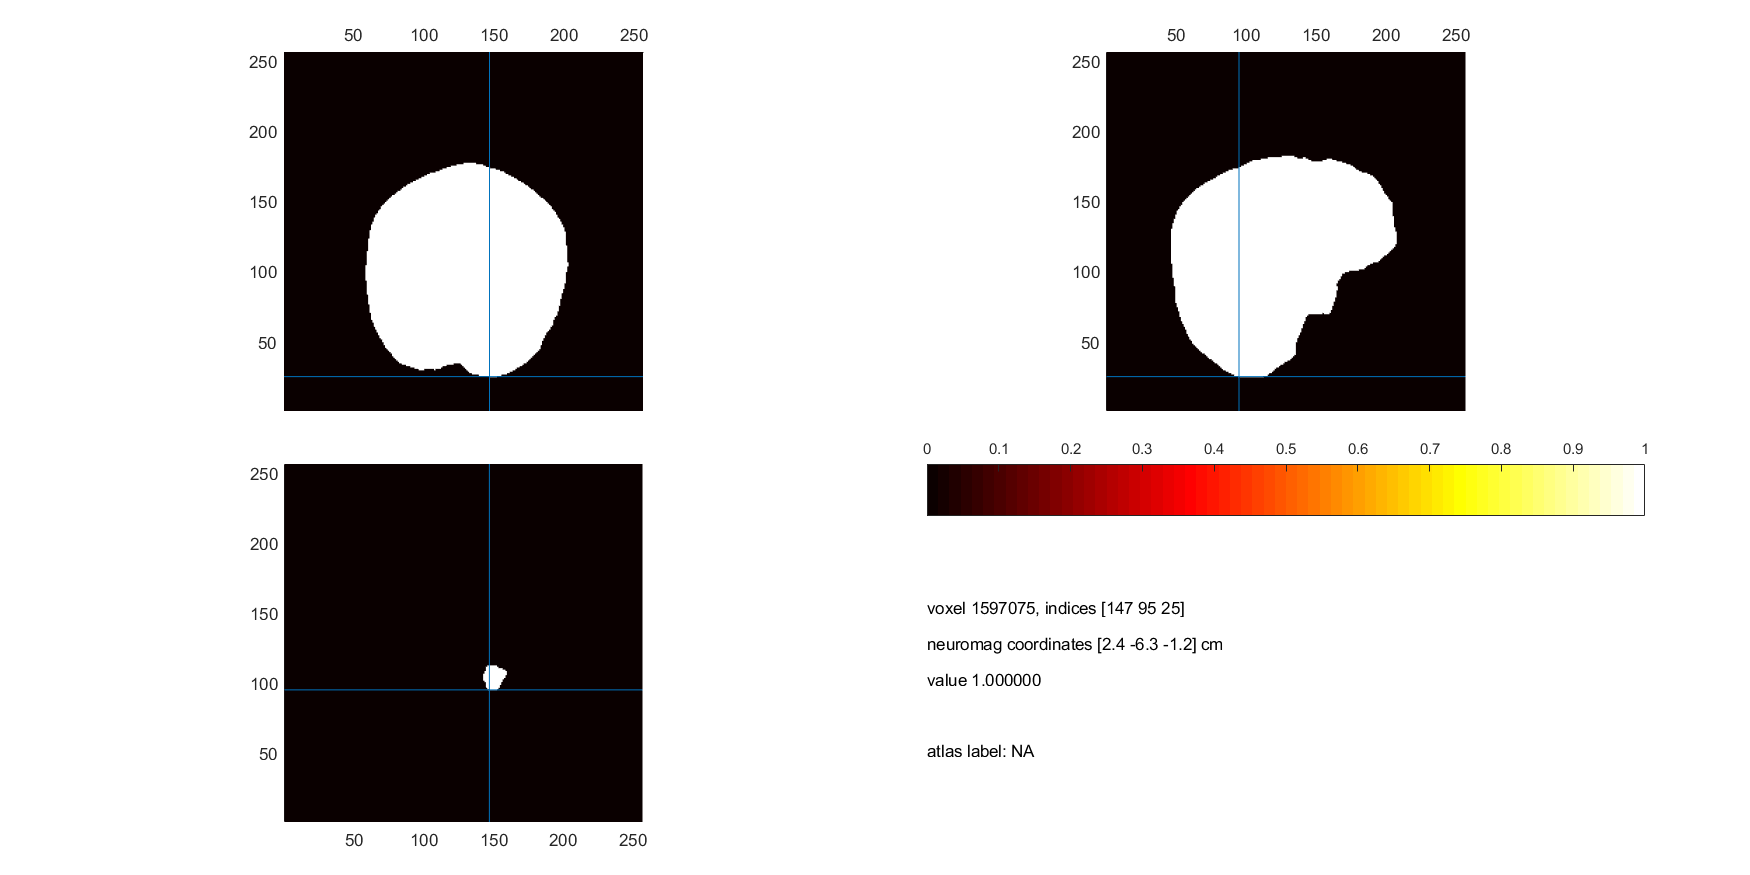

cfg = [];
cfg.funparameter = 'brain';
ft_sourceplot(cfg, mri_segm);

Next we will create the boundaries of the volume that belong to the brain with the ft_prepare_headmodel function, using a realistic single-shell method (Nolte, 2003). 

cfg=[];
cfg.grad=grad;
cfg.method='singleshell';
headmodel=ft_prepare_headmodel(cfg,mri_segm);

triangulating the outer boundary of compartment 1 (brain) with 3000 vertices
the call to "ft_prepare_mesh" took 5 seconds
the call to "ft_prepare_headmodel" took 6 seconds


headmodel=ft_convert_units(headmodel,'cm');

Plot the headmodel together with the channels and the digitized headshape points. 

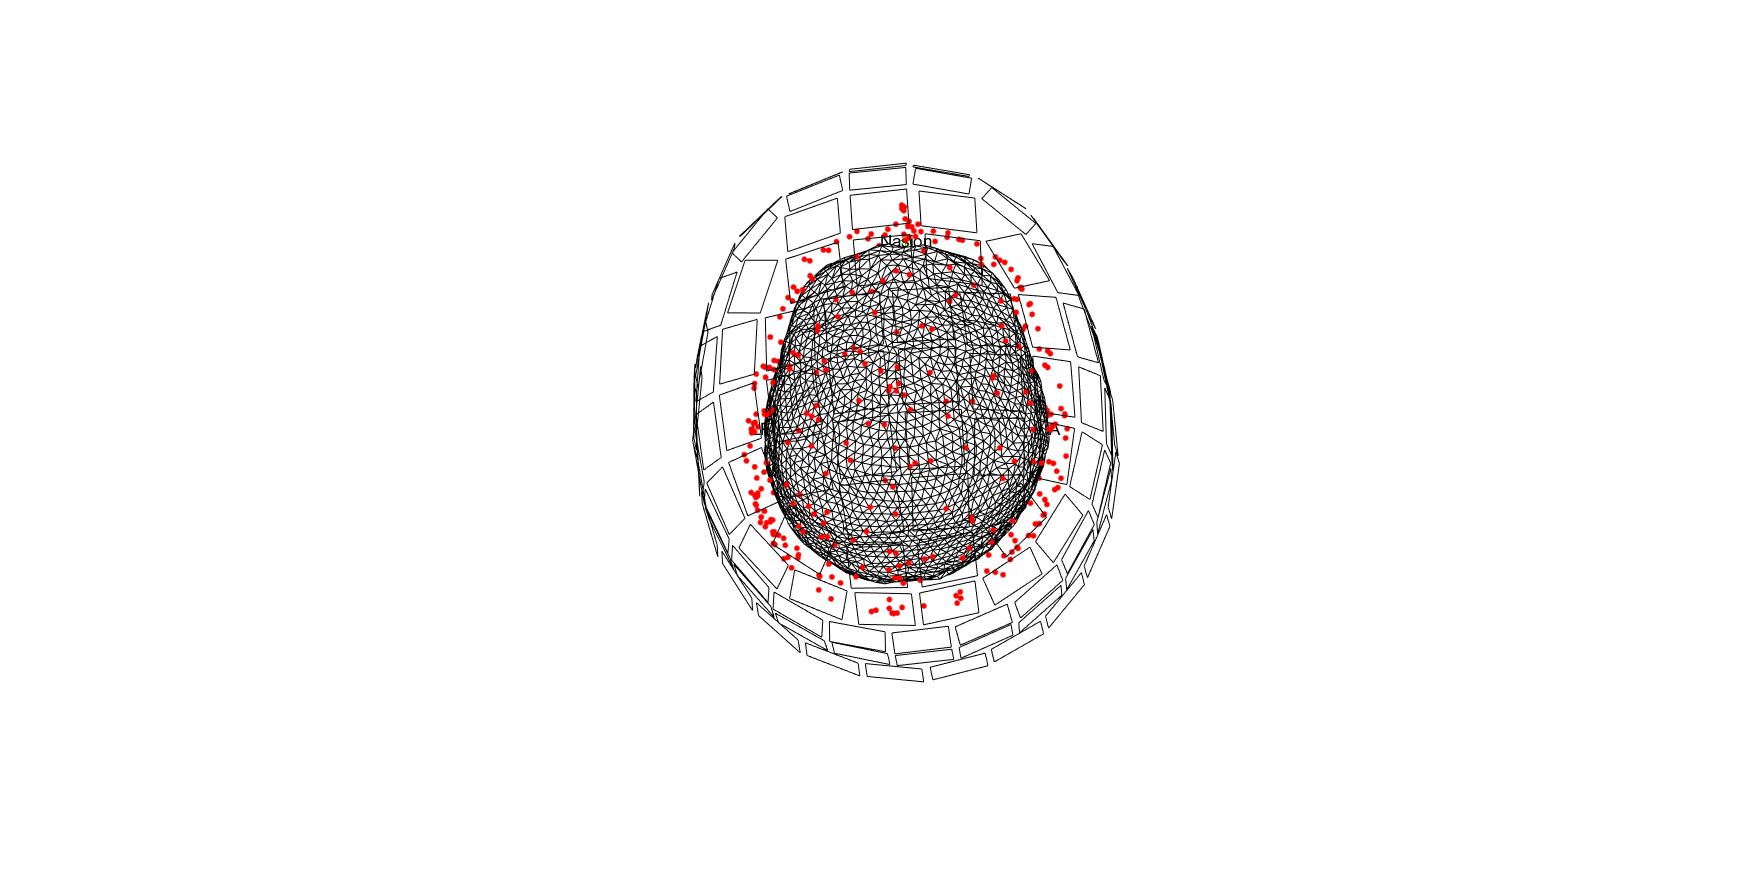

figure
ft_plot_sens(grad);
ft_plot_headshape(headshape);
ft_plot_headmodel(headmodel);

Now calculate the forward model by discretizing the brain volume into  gridpoints and calculating the leadfield matrix. Here we will have  gridpoints half a centimeter apart.   

cfg=[];
cfg.grad=grad;
cfg.headmodel=headmodel;
cfg.senstype='MEGGRAD';
cfg.grid.resolution=0.5;
cfg.grid.unit='cm';
cfg.normalize='yes';
cfg.channel=planar_clean.label;
grid=ft_prepare_leadfield(cfg);

 In ft_checkconfig at line 130
 In ft_prepare_leadfield at line 137



 In ft_checkconfig at line 325
 In ft_prepare_leadfield at line 157

using gradiometers specified in the configuration
computing surface normals
creating sourcemodel based on automatic 3D grid with specified resolution
using gradiometers specified in the configuration
creating 3D grid with 0.5 cm resolution
initial 3D grid dimensions are [37 41 35]
14921 dipoles inside, 38174 dipoles outside brain
making tight grid
14921 dipoles inside, 17479 dipoles outside brain
the call to "ft_prepare_sourcemodel" took 21 seconds
computing leadfield
computing leadfield 14921/14921

the call to "ft_prepare_leadfield" took 164 seconds


Plot the gridpoints and the channels.

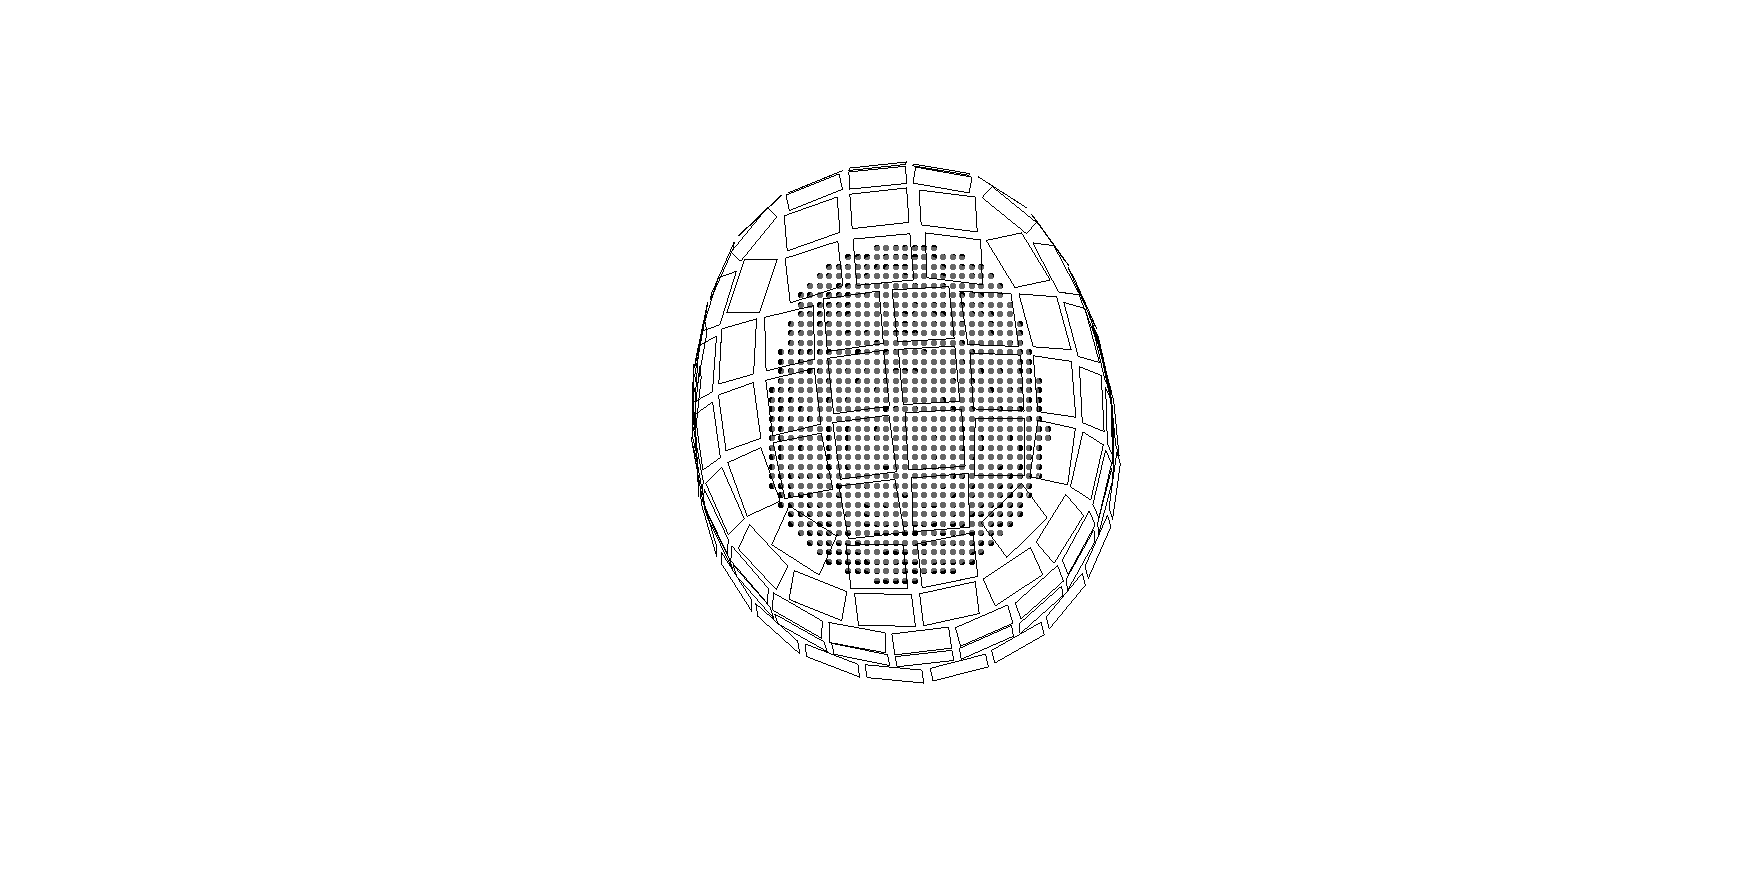

figure
ft_plot_sens(grad, 'style', '*b');
ft_plot_headmodel(headmodel, 'edgecolor', 'none'); alpha 0.4;
ft_plot_mesh(grid.pos(grid.inside,:));

Save the headmodel, the leadfield, the realigned mri structure and the sensor structure.

save([data_path,'headmodel_FLUX.mat'], 'headmodel')
save([data_path,'grid_FLUX.mat'], 'grid')
save([data_path,'mri_realign2_FLUX.mat'], 'mri_realigned2')
save([data_path,'grad_FLUX.mat'], 'grad')

## Preregistraion and publications

Publication, example:

"Structural magnetic resonance images (MRIs) were acquired using a 3  Tesla Siemens MAGNETOM Prisma whole-body scanner (Siemens AG; TE = 2 ms, and TR = 2 s). The raw T1 weighted images were converted from DICOM to NIFTI. The MRIs were de-faced to anonymize the participant. The  coordinate system of the participants' individual MRI was aligned to the anatomic landmarks (nasion as well as the left and right preauricular  points) and the scalp shapes digitized before the recordings. The  alignment according to the MEG sensor array was done relative to four  digitized head position indicator (HPI) coils. A single shell volume conduction model (Nolte, 2003) was constructed. This was  then used to construct a volumetric forward model (5 mm grid) covering  the full brain volume. The lead field matrix was then calculated according the head-position with respect to MEG sensor array. "

## References

Nolte, G. (2003). The magnetic lead field theorem in the quasi-static  approximation and its use for magnetoencephalography forward calculation in realistic volume conductors. *Physics in Medicine & Biology*, *48*(22), 3637.